clear

syms x0 y0 v0 gamma0 g t x

a = [0; -g]

$$a = \left(\begin{array}{c} 0\\ -g \end{array}\right)$$

v = [v0*cos(gamma0); v0*sin(gamma0)] + int(a, t)

$$v = \left(\begin{array}{c} v_{0}\,\cos\left(\gamma_{0}\right)\\ v_{0}\,\sin\left(\gamma_{0}\right)-g\,t \end{array}\right)$$

expr = x == x0 + int(v(1), t)

$$expr = x=x_{0}+t\,v_{0}\,\cos\left(\gamma_{0}\right)$$

y = y0 + int(v(2), t)

$$y = -\frac{g\,t^{2}}{2}+v_{0}\,\sin\left(\gamma_{0}\right)\,t+y_{0}$$


y = simplify(subs(y, t, solve(expr, t)))

$$y = y_{0}+\frac{\sin\left(\gamma_{0}\right)\,\left(x-x_{0}\right)}{\cos\left(\gamma_{0}\right)}-\frac{g\,{\left(x-x_{0}\right)}^{2}}{2\,{v_{0}}^{2}\,{\cos\left(\gamma_{0}\right)}^{2}}$$


g = 9.8065;
x0 = 0; y0 = 0;
v0 = 10; gamma0 = 45*pi/180;

y = subs(y)

$$y = x-\frac{19613\,x^{2}}{200000}$$

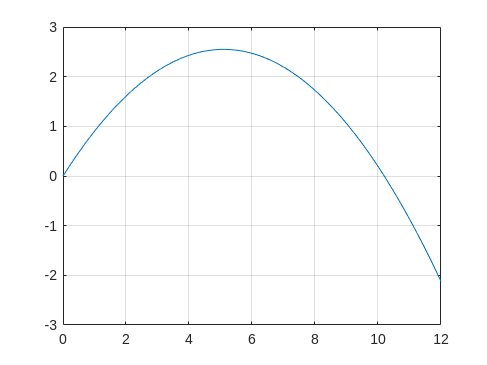


x = 0:0.1:12;
y = subs(y);

plot(x, y);
grid on;